Inicializácia

clc; clear; clf;
n0 = 1;%index prveho suboru
n = 6;%pocet suborov

Vykreslenie nameraných dát

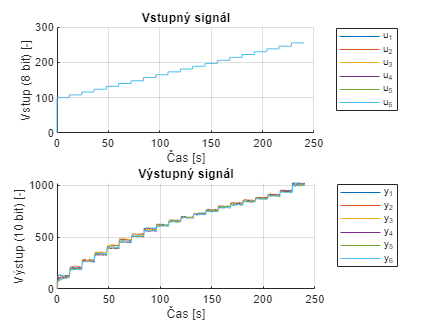

figure;
for i=n0:n0+n-1
    fileName = ['./../TP-PlainData/allSig_log_prev_mer',num2str(i),'_up.csv'];
    dt = csvread(fileName);
    subplot(2,1,1);
    txt = ['u_',num2str(i)];
    hold on;
    plot(dt(:,1),dt(:,2),'DisplayName',txt);
    hold off;
    subplot(2,1,2);
    txt = ['y_',num2str(i)];
    hold on;
    plot(dt(:,1),dt(:,3),'DisplayName',txt);
    hold off;
end
subplot(2,1,1);
grid on;
title('Vstupný signál');
legend("Location",'bestoutside');
xlabel('Čas [s]');ylabel('Vstup (8 bit) [-]');
subplot(2,1,2);
grid on;
title('Výstupný signál');
legend("Location",'bestoutside');
xlabel('Čas [s]');ylabel('Výstup (10 bit) [-]');

Získanie ustálených hodnôt výstupu z nameraných dát

m = 19;%predpoklad pocet derivacii vstupu (zmeny vstupu)
w = 80;%Pocet dat povaz ako ustalene
dataStore = zeros((m+1)*w,n+2);
for i=1:n
    fileName = ['./../TP-PlainData/allSig_log_prev_mer',num2str((n0-1)+i),'_up.csv'];
    dt = csvread(fileName);
    %dt = dt(2:end,:);
    diffVal = diff(dt(2:end,2));
    ids = find(or(diffVal > 0,diffVal < 0));
    ln = size(ids,1);
    if ln == m
        ln = size(dt,1);
        id = ids;
        for j=1:m
            if i == 1
                dataStore(1+w*(j-1):w*j,1) = dt(id(j):id(j)+w-1,1);
                dataStore(1+w*(j-1):w*j,2) = dt(id(j):id(j)+w-1,2);
            end
            dataStore(1+w*(j-1):w*j,i+2) = dt(id(j):id(j)+w-1,3);
        end
    end
end

Vykreslenie získaných ustálených dát

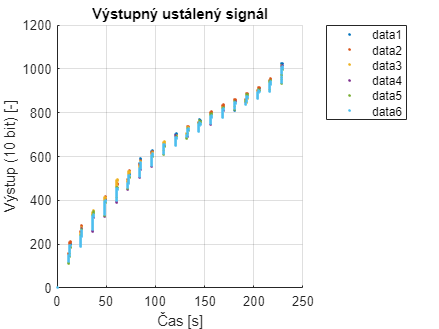

figure;
hold on;
for i=1:n
    plot(dataStore(:,1), dataStore(:,2+i),'.');
end
hold off;
grid on;
title('Výstupný ustálený signál');
legend("Location",'bestoutside');
xlabel('Čas [s]');ylabel('Výstup (10 bit) [-]');

dataInputIds =  find(diff(dataStore(:,2))>0);
dataInputStore = dataStore(dataInputIds, 2);
nT = 1;
indetStore = zeros(m-1,3+nT);

for i=2:m

Určenie dynamiky pracovného bodu

    %p0 = 206;%Pracovny bod pred Jed. skok
    %p = 214;%Pracovny bod po Jed. skoku
    p0 = dataInputStore(i-1);
    p = dataInputStore(i);
    pIds = find(dataStore(:,2)==p);
    pData = dataStore(pIds,:);
    
    pDataMean = zeros(w,3);
    pDataMean(:,1:2) = pData(:,1:2);
    pomDt = pData(:,3:end)';
    pDataMean(:,3) = mean(pomDt);

Vykreslenie

    figure;
    hold on;
    plot(pDataMean(1:end-2,1), pDataMean(1:end-2,3),'DisplayName','y');
    hold off;
    grid on;
    txt = ['Výstupný ustálený signál (p)= ',num2str(p)];
    title(txt);
    legend("Location",'bestoutside');
    xlabel('Čas [s]');ylabel('Výstup (10 bit) [-]');

Zápis hodnoty y

    indetStore(i-1,4) = pDataMean(1,3);

Normalizovanie

    pDataMean(:,1) = pDataMean(:,1) - pDataMean(1,1);
    pDataMean(:,2) = pDataMean(:,2) - p0;
    pDataMean(:,3) = pDataMean(:,3) - pDataMean(1,3);

Vykreslenie

    figure;
    hold on;
    plot(pDataMean(1:end-2,1), pDataMean(1:end-2,3),'DisplayName','y');
    hold off;
    grid on;
    txt = ['Výstupný ustálený signál (p)= ',num2str(p)];
    title(txt);
    legend("Location",'bestoutside');
    xlabel('Čas [s]');ylabel('Výstup (10 bit) [-]');

Identifikácia

    t = pDataMean(1:end-2,1);
    u = pDataMean(1:end-2,2);
    y = pDataMean(1:end-2,3);

Sústava 1. rádu

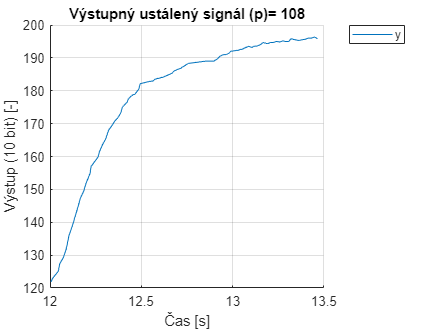

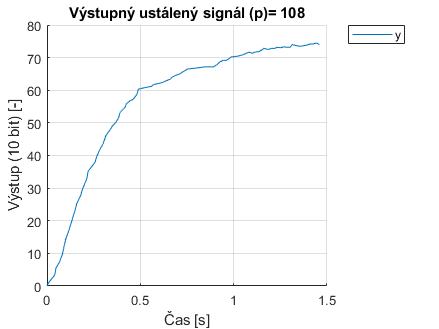

y1_v = 24.4200

y2_v = 51.8000

y1 = 25.3333

t1 = 0.1600

y2 = 53.1667

t2 = 0.3910

T = 0.2876

D = 0.0450

G1_B =
 
                     9.223
  exp(-0.045*s) * ------------
                  0.2876 s + 1
 
Continuous-time transfer function.



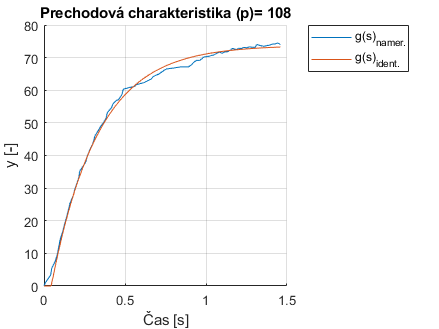

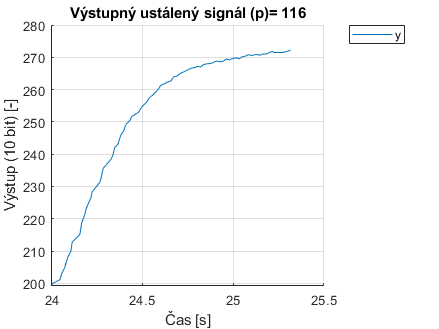

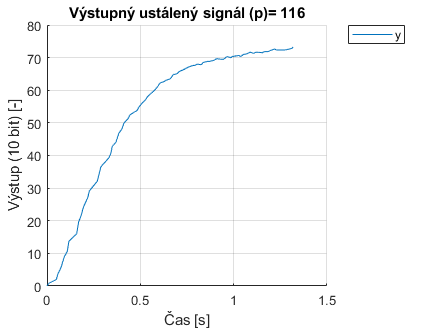

y1_v = 24.1450

y2_v = 51.2167

y1 = 24.3333

t1 = 0.1960

y2 = 51.3333

t2 = 0.4350

T = 0.2976

D = 0.0770

G1_B =
 
                     9.034
  exp(-0.077*s) * ------------
                  0.2976 s + 1
 
Continuous-time transfer function.



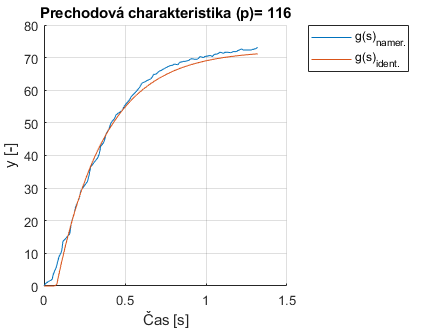

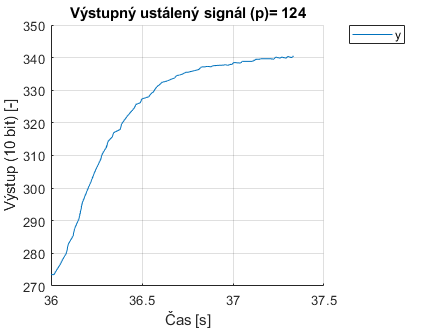

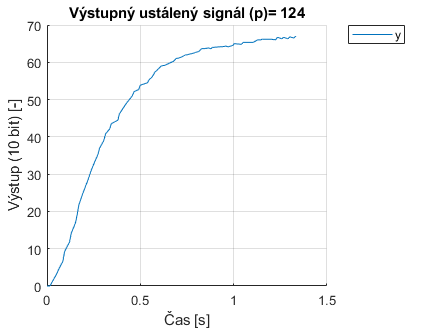

y1_v = 22.1100

y2_v = 46.9000

y1 = 24

t1 = 0.1860

y2 = 47.6667

t2 = 0.4070

T = 0.2751

D = 0.0759

G1_B =
 
                      8.305
  exp(-0.0759*s) * ------------
                   0.2751 s + 1
 
Continuous-time transfer function.



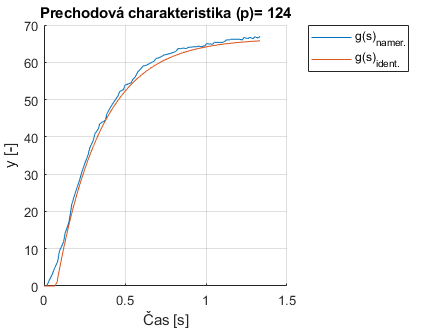

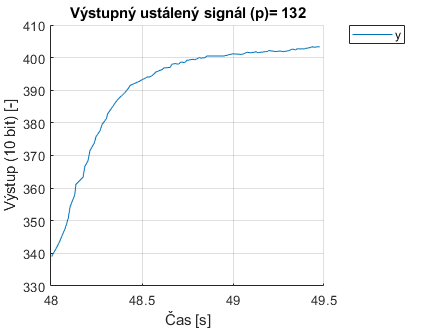

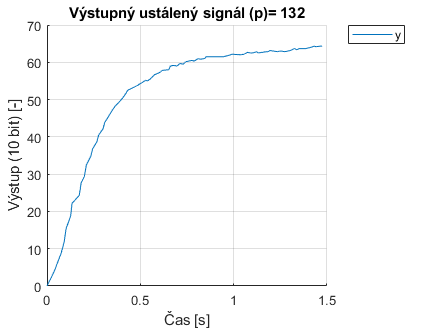

y1_v = 21.2300

y2_v = 45.0333

y1 = 22.1667

t1 = 0.1340

y2 = 46

t2 = 0.3360

T = 0.2515

D = 0.0334

G1_B =
 
                      7.983
  exp(-0.0334*s) * ------------
                   0.2515 s + 1
 
Continuous-time transfer function.



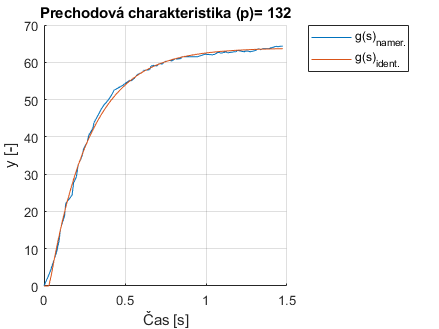

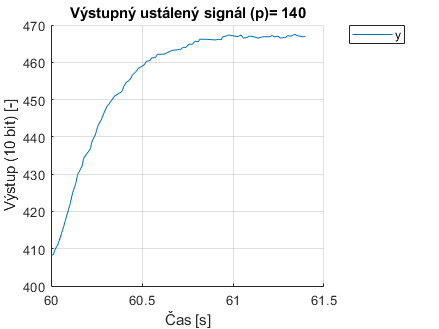

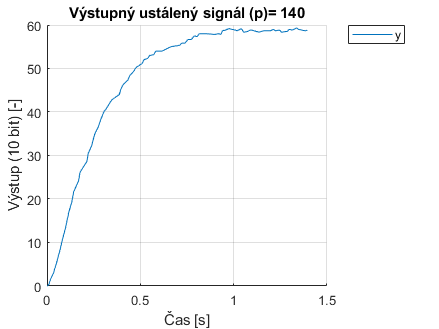

y1_v = 19.4150

y2_v = 41.1833

y1 = 21.6667

t1 = 0.1430

y2 = 42.3333

t2 = 0.3400

T = 0.2453

D = 0.0449

G1_B =
 
                      7.347
  exp(-0.0449*s) * ------------
                   0.2453 s + 1
 
Continuous-time transfer function.



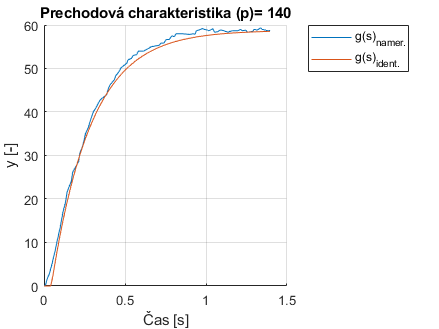

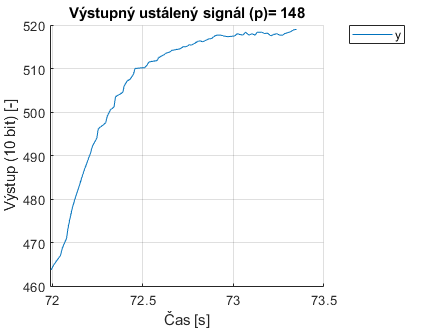

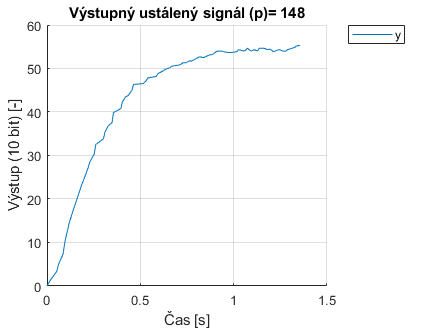

y1_v = 18.2600

y2_v = 38.7333

y1 = 19

t1 = 0.1530

y2 = 39.8333

t2 = 0.3560

T = 0.2527

D = 0.0519

G1_B =
 
                      6.805
  exp(-0.0519*s) * ------------
                   0.2527 s + 1
 
Continuous-time transfer function.



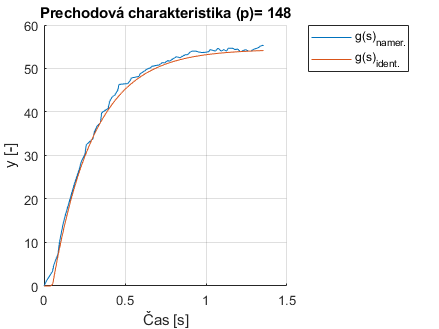

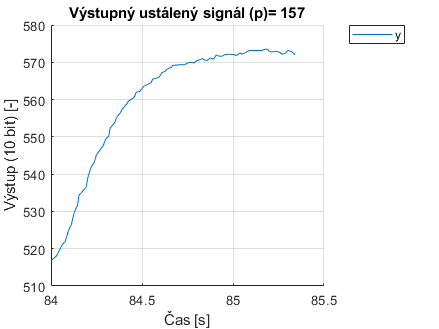

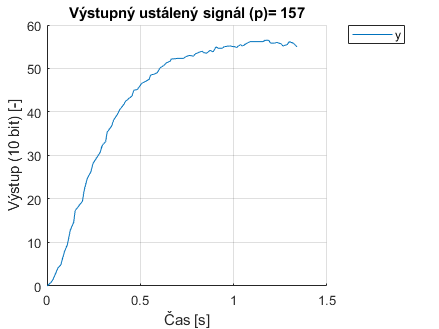

y1_v = 18.1500

y2_v = 38.5000

y1 = 19.5000

t1 = 0.1900

y2 = 39.5000

t2 = 0.3780

T = 0.2341

D = 0.0964

G1_B =
 
                      6.202
  exp(-0.0964*s) * ------------
                   0.2341 s + 1
 
Continuous-time transfer function.



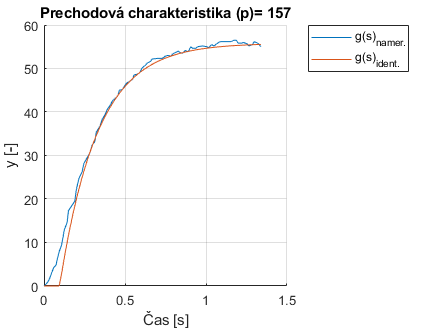

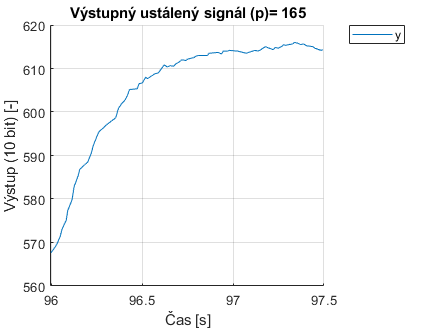

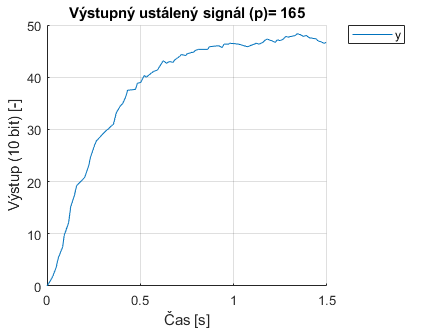

y1_v = 15.4000

y2_v = 32.6667

y1 = 17.5000

t1 = 0.1480

y2 = 33.1667

t2 = 0.3710

T = 0.2776

D = 0.0369

G1_B =
 
                      5.941
  exp(-0.0369*s) * ------------
                   0.2776 s + 1
 
Continuous-time transfer function.



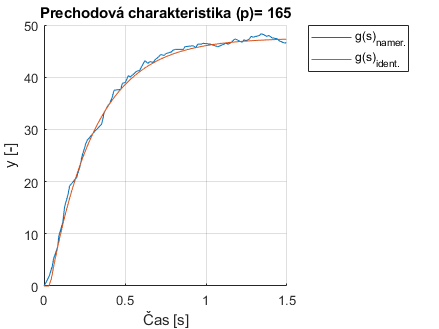

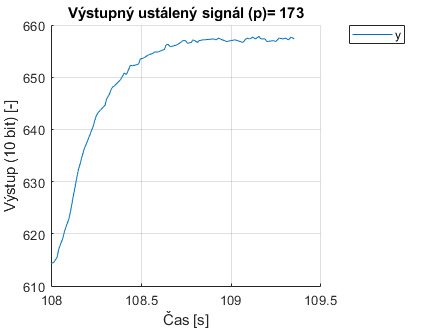

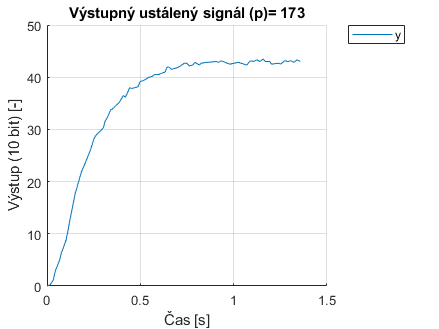

y1_v = 14.1900

y2_v = 30.1000

y1 = 14.8333

t1 = 0.1350

y2 = 30.3333

t2 = 0.3020

T = 0.2079

D = 0.0518

G1_B =
 
                      5.364
  exp(-0.0518*s) * ------------
                   0.2079 s + 1
 
Continuous-time transfer function.



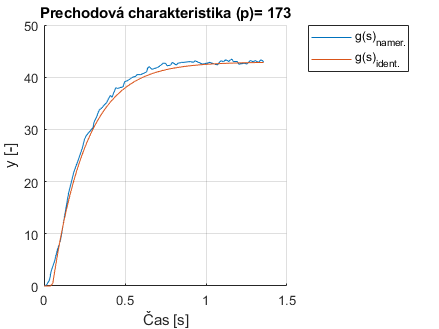

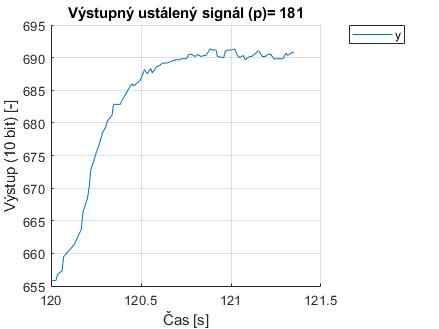

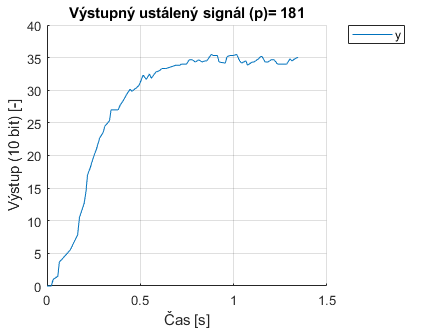

y1_v = 11.5500

y2_v = 24.5000

y1 = 12.6667

t1 = 0.1990

y2 = 24.5000

t2 = 0.3100

T = 0.1382

D = 0.1437

G1_B =
 
                     4.307
  exp(-0.144*s) * ------------
                  0.1382 s + 1
 
Continuous-time transfer function.



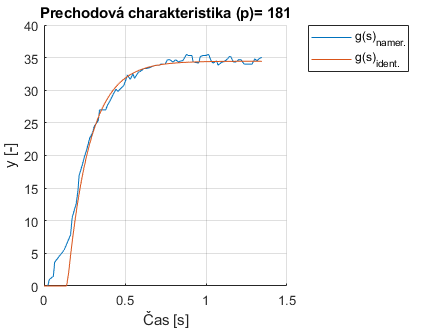

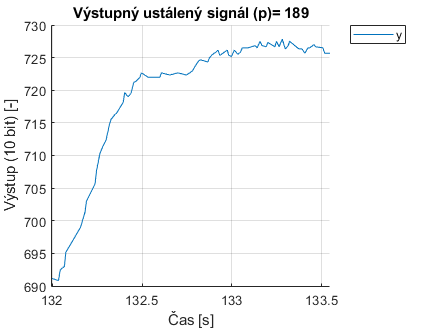

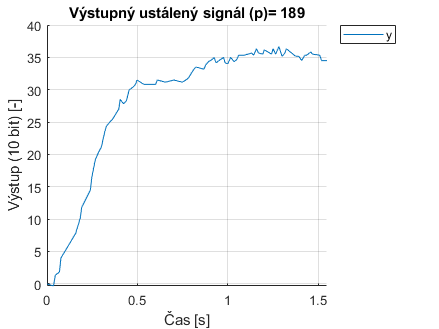

y1_v = 11.3850

y2_v = 24.1500

y1 = 11.8333

t1 = 0.1920

y2 = 24.3333

t2 = 0.3280

T = 0.1693

D = 0.1243

G1_B =
 
                     4.383
  exp(-0.124*s) * ------------
                  0.1693 s + 1
 
Continuous-time transfer function.



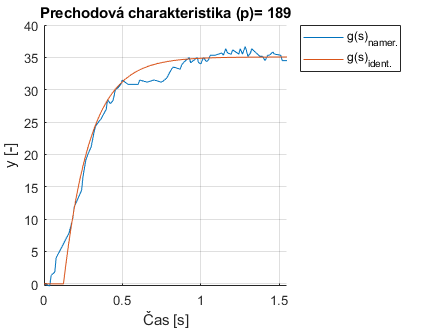

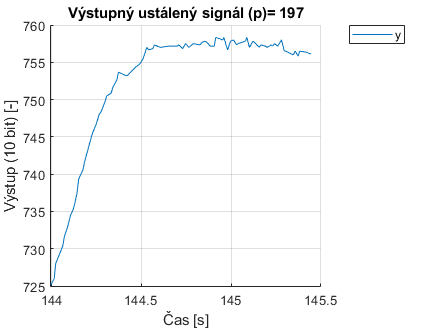

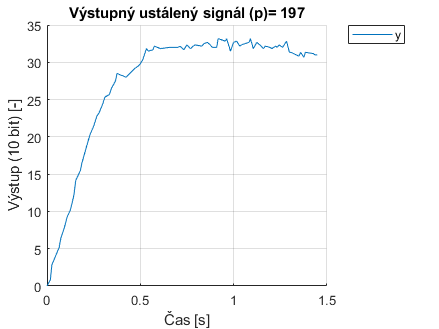

y1_v = 10.2300

y2_v = 21.7000

y1 = 12.1667

t1 = 0.1440

y2 = 22.8333

t2 = 0.2680

T = 0.1544

D = 0.0822

G1_B =
 
                      3.919
  exp(-0.0822*s) * ------------
                   0.1544 s + 1
 
Continuous-time transfer function.



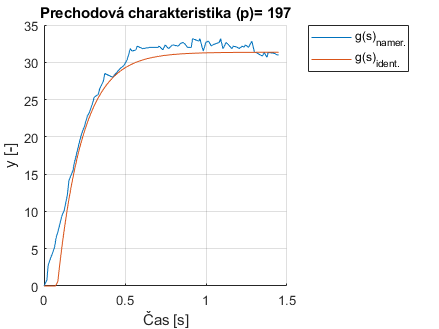

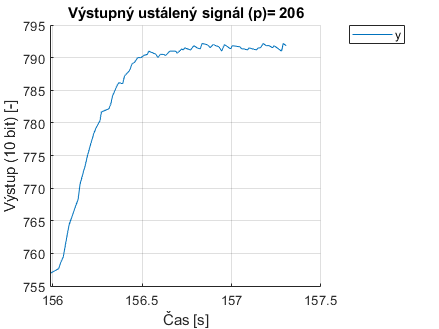

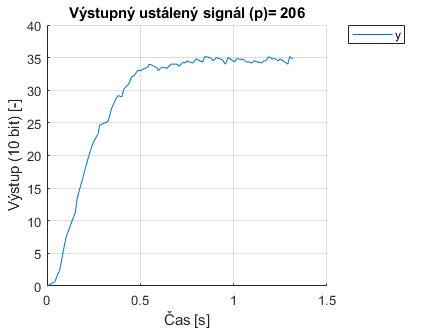

y1_v = 11.4950

y2_v = 24.3833

y1 = 13.5000

t1 = 0.1620

y2 = 24.6667

t2 = 0.2820

T = 0.1494

D = 0.1022

G1_B =
 
                     3.852
  exp(-0.102*s) * ------------
                  0.1494 s + 1
 
Continuous-time transfer function.



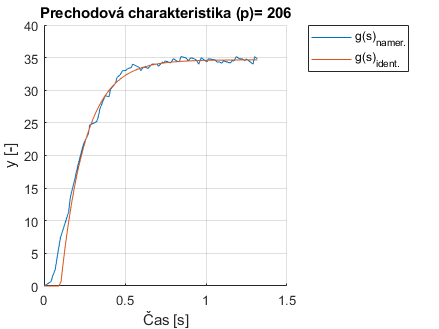

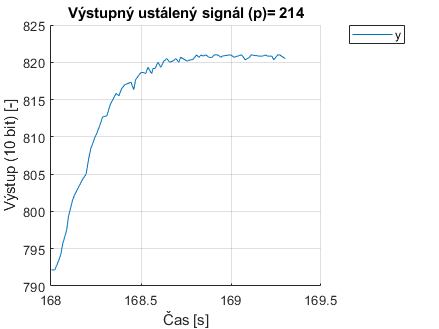

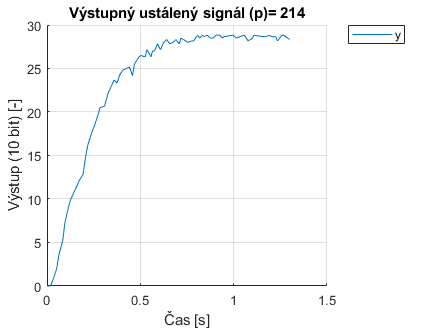

y1_v = 9.3500

y2_v = 19.8333

y1 = 10

t1 = 0.1280

y2 = 19.8333

t2 = 0.2760

T = 0.1843

D = 0.0543

G1_B =
 
                       3.58
  exp(-0.0543*s) * ------------
                   0.1843 s + 1
 
Continuous-time transfer function.



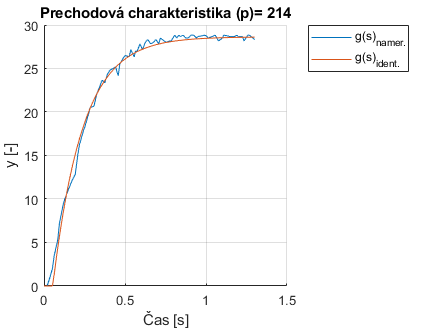

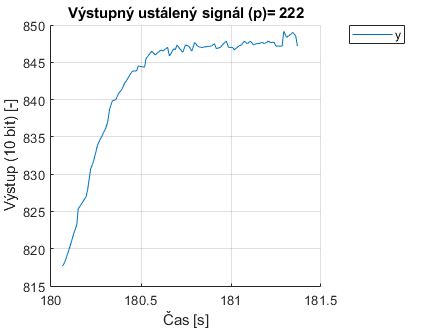

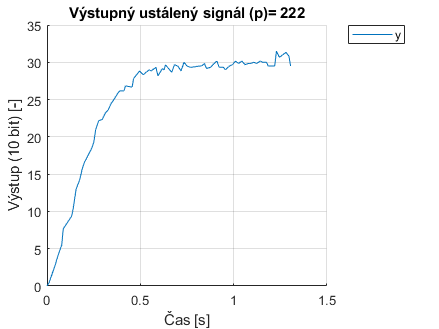

y1_v = 9.7350

y2_v = 20.6500

y1 = 10.1667

t1 = 0.1390

y2 = 21

t2 = 0.2610

T = 0.1519

D = 0.0782

G1_B =
 
                      3.795
  exp(-0.0782*s) * ------------
                   0.1519 s + 1
 
Continuous-time transfer function.



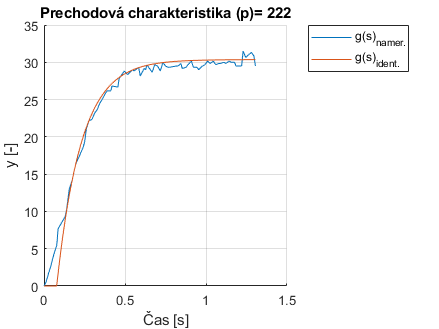

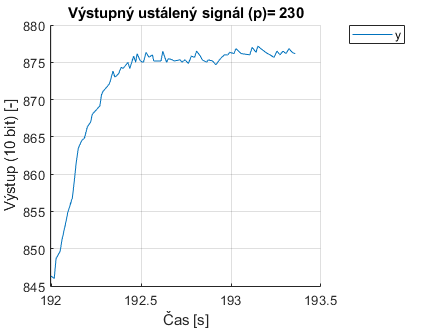

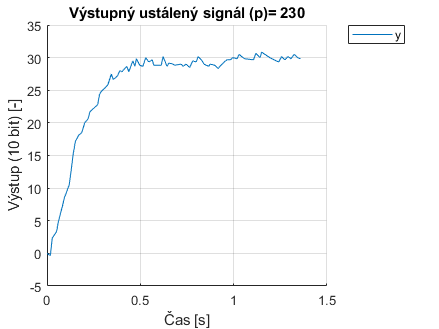

y1_v = 9.8450

y2_v = 20.8833

y1 = 10.5000

t1 = 0.1190

y2 = 21.6667

t2 = 0.2290

T = 0.1370

D = 0.0642

G1_B =
 
                      3.754
  exp(-0.0642*s) * -----------
                   0.137 s + 1
 
Continuous-time transfer function.



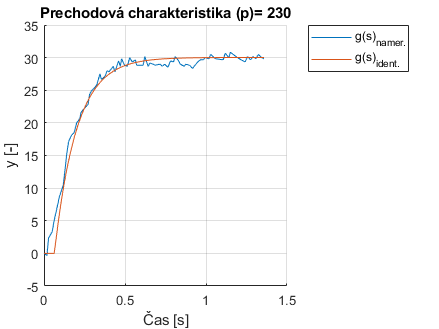

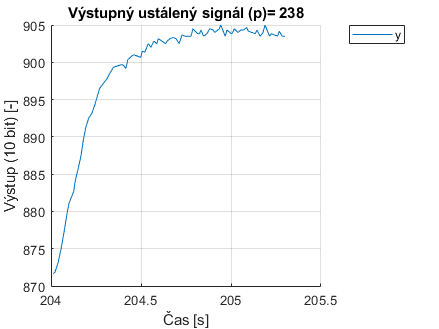

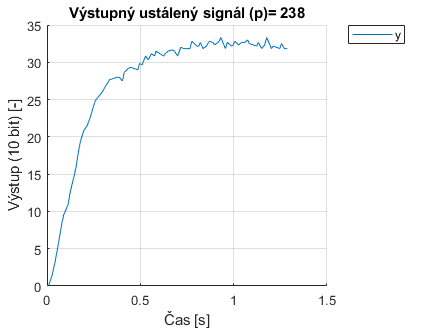

y1_v = 10.5050

y2_v = 22.2833

y1 = 11

t1 = 0.1140

y2 = 22.6667

t2 = 0.2320

T = 0.1469

D = 0.0552

G1_B =
 
                      4.027
  exp(-0.0552*s) * ------------
                   0.1469 s + 1
 
Continuous-time transfer function.



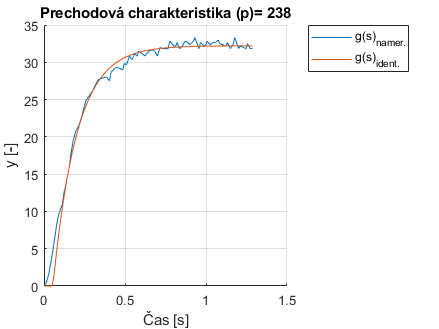

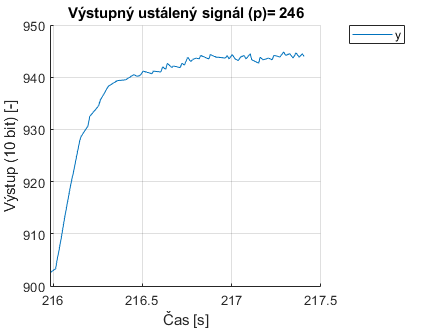

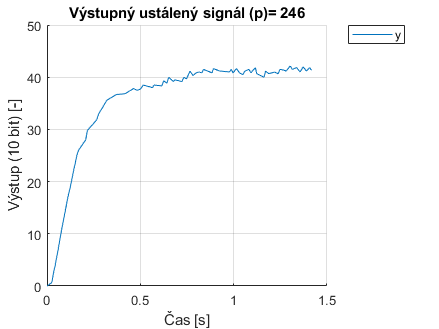

y1_v = 13.6400

y2_v = 28.9333

y1 = 16.8333

t1 = 0.1110

y2 = 29.8333

t2 = 0.2170

T = 0.1320

D = 0.0582

G1_B =
 
                      5.191
  exp(-0.0582*s) * -----------
                   0.132 s + 1
 
Continuous-time transfer function.



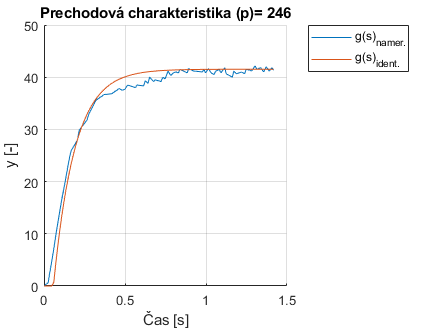

    y1_v = 0.33*y(end)
    y2_v = 0.70*y(end)
    
    yMean = mean(y(end-10:end));
    
    K = yMean/u(1);
    
    [r,c] = find(y>=y1_v,1,"first");
    y1 = y(r,c)
    t1 = t(r,c)
    
    [r,c] = find(y>=y2_v,1,"first");
    y2 = y(r,c)
    t2 = t(r,c)
    s = tf("s");
    T = 1.245*(t2-t1)
    D = 1.498*t1 - 0.498*t2
    G1_B = (K)/(1+T*s)*exp(-(D*s))
    opt = stepDataOptions('InputOffset',0,'StepAmplitude',p-p0);
    [st_y,st_t] = step(G1_B,t(end),opt);
    figure;
    hold on;
    plot(t,y,'DisplayName','g(s)_{namer.}');
    plot(st_t,st_y,'DisplayName','g(s)_{ident.}');
    hold off;
    grid on;
    xlabel('Čas [s]');
    ylabel('y [-]');
    txt = ['Prechodová charakteristika (p)= ',num2str(p)];
    title(txt);
    legend('Location','bestoutside');
    indetStore(i-1,1) = p;
    indetStore(i-1,2) = K;
    indetStore(i-1,3) = T;
end

Vykreslenie identifikovaných parametrov

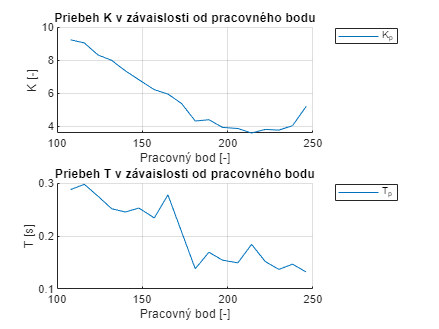

figure;
subplot(2,1,1);
hold on;
plot(indetStore(:,1), indetStore(:,2),'DisplayName','K_p');
hold off;
grid on;
title('Priebeh K v závaislosti od pracovného bodu');
legend("Location",'bestoutside');
xlabel('Pracovný bod [-]');ylabel('K [-]');
subplot(2,1,2);
hold on;
plot(indetStore(:,1), indetStore(:,3),'DisplayName','T_p');
hold off;
grid on;
title('Priebeh T v závaislosti od pracovného bodu');
legend("Location",'bestoutside');
xlabel('Pracovný bod [-]');ylabel('T [s]');

Tredovanie

%K
[pK, SK] = polyfit(indetStore(:,1),indetStore(:,2),3)

pK =     0.0000   -0.0028    0.3497   -3.9015


SK = struct with fields:
        R: [4×4 double]
       df: 14
    normr: 0.7361


x1 = indetStore(:,1);
[y1K,deltaK] = polyval(pK,x1,SK);
%T
[pT, ST] = polyfit(indetStore(:,1),indetStore(:,3),3)

pT =     0.0000   -0.0001    0.0074   -0.0088


ST = struct with fields:
        R: [4×4 double]
       df: 14
    normr: 0.0944


x1 = indetStore(:,1);
[y1T,deltaT] = polyval(pT,x1,ST);

Vykreslenie

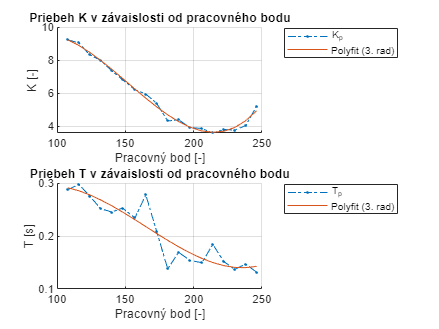

figure;
subplot(2,1,1);
hold on;
plot(indetStore(:,1), indetStore(:,2),'.-.','DisplayName','K_p');
plot(x1, y1K,'DisplayName','Polyfit (3. rad)');
hold off;
grid on;
title('Priebeh K v závaislosti od pracovného bodu');
legend("Location",'bestoutside');
xlabel('Pracovný bod [-]');ylabel('K [-]');
subplot(2,1,2);
hold on;
plot(indetStore(:,1), indetStore(:,3),'.-.','DisplayName','T_p');
plot(x1, y1T,'DisplayName','Polyfit (3. rad)');
hold off;
grid on;
title('Priebeh T v závaislosti od pracovného bodu');
legend("Location",'bestoutside');
xlabel('Pracovný bod [-]');ylabel('T [s]');

sim_u = dt(:,1:2);